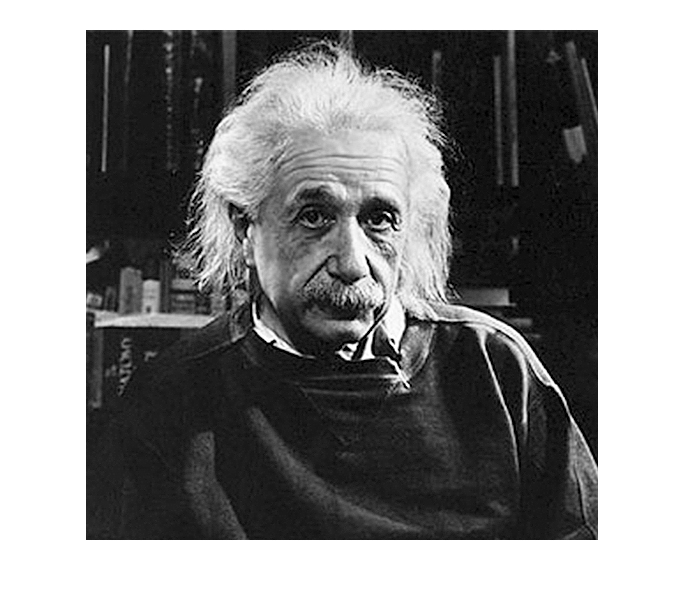

% Read images
E1 = imread("images\Einstein1.jpg");
E2 = imread("images\Einstein2.jpg");
E1 = im2double(E1);
E2 = im2double(E2);
imshow(E1)

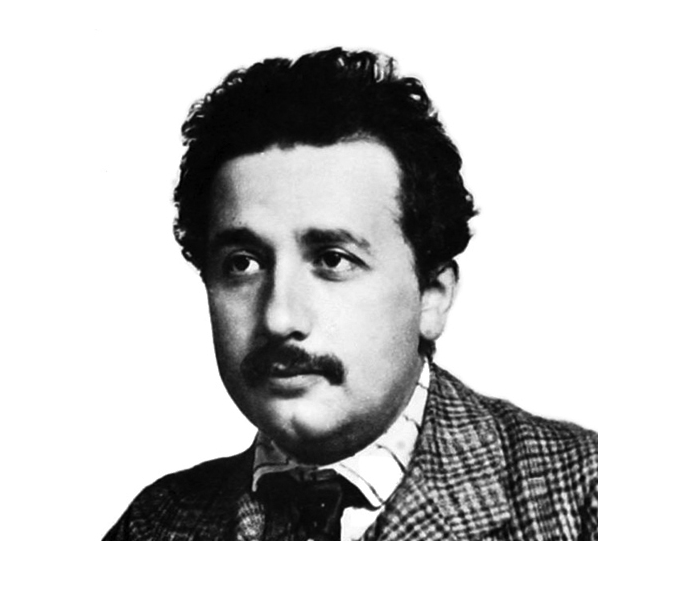

imshow(E2)

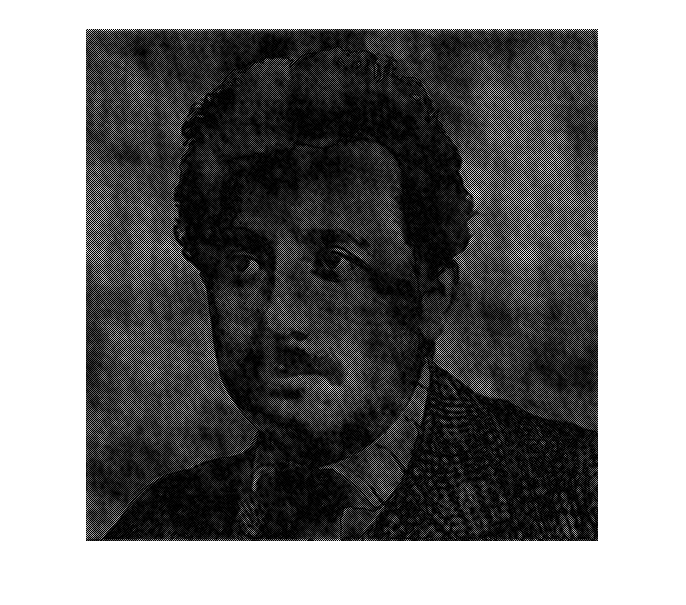


% Fourier spectrum of images
F1 = fftshift(fft2(E1));
F2 = fftshift(fft2(E2));

ang1 = angle(F1);
ang2 = angle(F2);
S1 = abs(F1);
S2 = abs(F2);

E1_E2 = real(ifft2(S1.*exp(i * ang2)));
imshow(E1_E2)

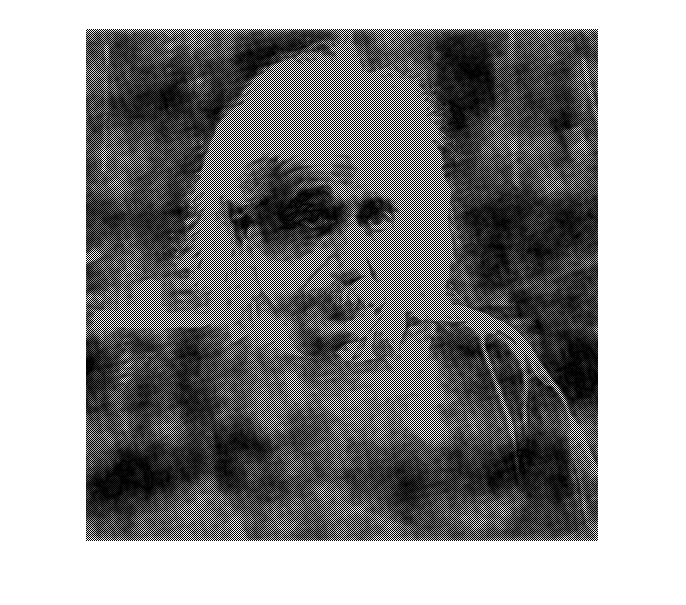

imwrite(E1_E2,"images\E1_E2.png");

E2_E1 = real(ifft2(S2.*exp(i * ang1)));
imshow(E2_E1)

imwrite(E2_E1, 'images\E2_E1.png')